clc;
close all;
clear variables;

### Simulacija

Parametri simulacije

sim_file_name = "buck_boost_DCDC_sim";
open_system(sim_file_name);

sim_duration = 1; % sec
time_step = 1e-4;

Propusni opseg

w0 = 150; % rad/s
w_diff = w0 * 20; % da bude dovoljno van propusnog opsega
w_prefiltar = 0.667 * w0; % odokativno

Feedback linearizacija

p = 3*w0; %trostruki pol da bi prop opseg bio w0

k_i = p^3;
k_0 = 3*p^2;
k_1 = 3*p;
K_fl = [k_i,k_0,k_1];

subsystem_name = "/Feedback linearizacija";

feedback_linearizacija_foo(sim_file_name, subsystem_name)

Sliding mode control

beta = 10000;
p = 2*w0;
K_0 = 2*p;
K_i = p^2;
K_smc = [K_i, K_0];

K_smc_0 = [0, K_smc];

subsystem_name = "/Klizno upravljanje";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)


Boundry layer sliding mode control

phi = beta / 20 / p;
subsystem_name = "/Klizno upravljanje sa granicnim slojem";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)

Parametri sistema

[L, R, C, E, x_2e] = nominalni_parametri();

Referenca i poremecaj

t_ref = [1/6, 2/6, 3/6, 4/6 ] * sim_duration;
step_ref = [0.5, -0.5, -0.5, 0.5] * x_2e;

t_poremecaj = [5/6] * sim_duration;
step_poremecaj = [1/3] * E;

Opsti parametri kontrolera

R_dot_enable = 1;
prefiltar_enable = 1;
noise_enable = 0;

sigma_noise = 0.01 * abs(x_2e);


% "smc", "fbl", "bl smc"
ime_kontrolera = "bl smc";

Simulacija

C_nom = C;
relative_vals = [0.8, 0.9, 1.0, 1.1, 1.2];
C_array = relative_vals .* C_nom;

for i = 1:length(C_array)
    C = C_array(i);
    out(i) = sim(sim_file_name);
end

### Crtanje

main_plot_linewidth = 1;
auxiliary_plot_linewidth = 0.5;


#### Izlaz

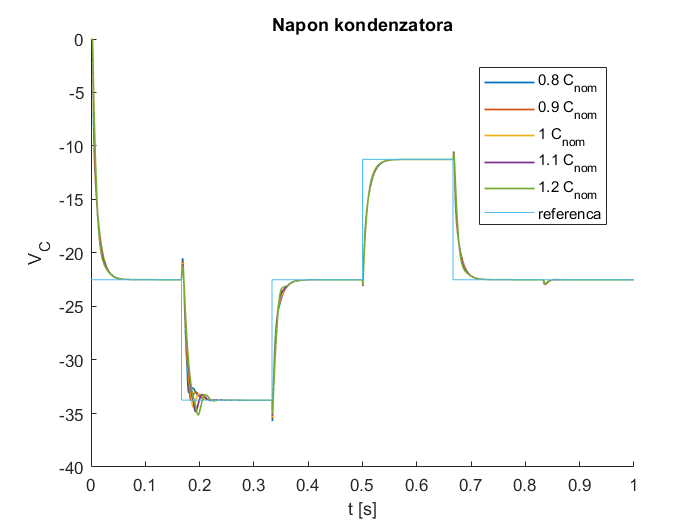

y_oznaka = "V_C";
naslov = "Napon kondenzatora";
ref_flg = false;
poremecaj_flg = false;

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
    labels{i} = relative_vals(i) + " C_{nom}";
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), 0, sim_duration);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

Prelazak ka nominalnom rezimu rada

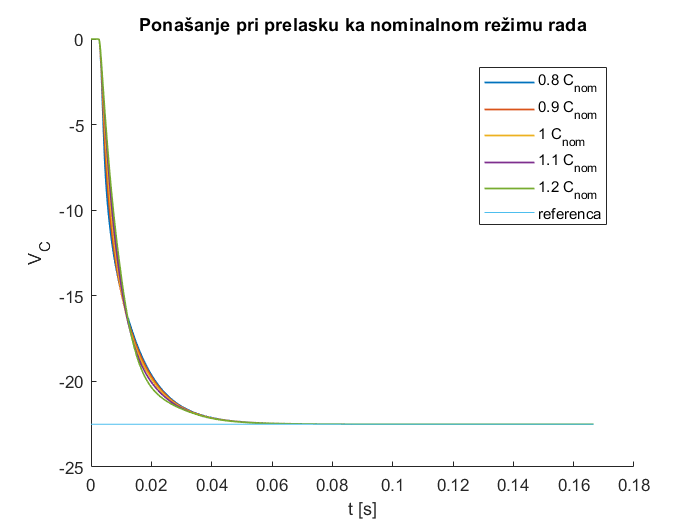

naslov = "Ponašanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = t_ref(1);

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = relative_vals(i) + " C_{nom}";
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

Odziv na referencu

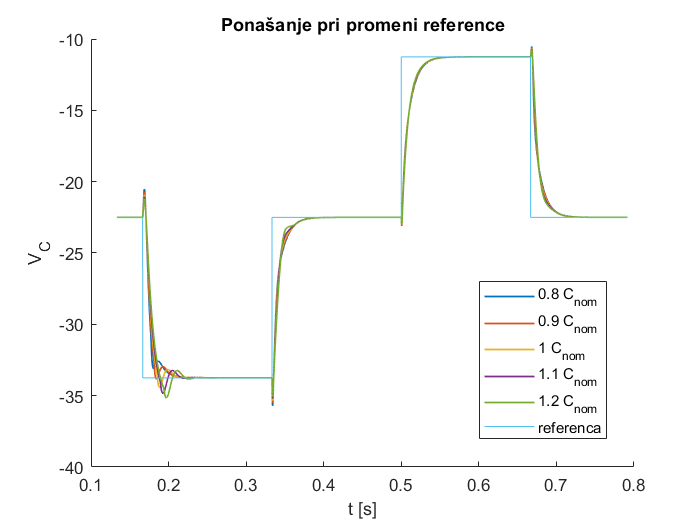

naslov = "Ponašanje pri promeni reference";
t_start = 0.8*t_ref(1);
t_end = 0.95*t_poremecaj(1);

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = relative_vals(i) + " C_{nom}";
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

Poremecaj

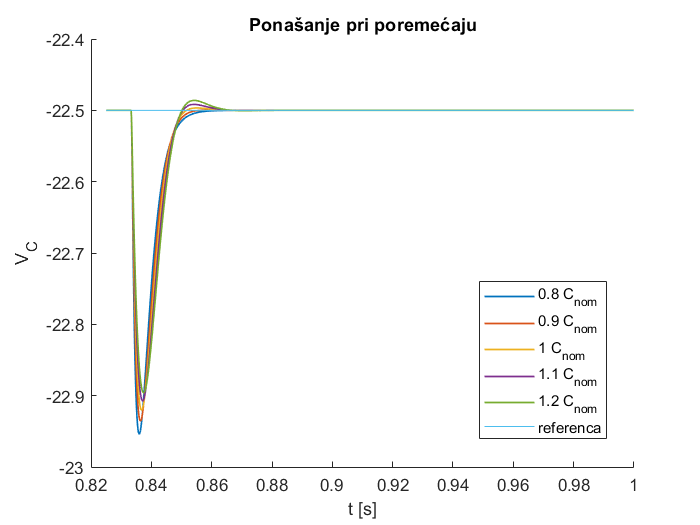

naslov = "Ponašanje pri poremećaju";
t_start = 0.99 * t_poremecaj(1);
t_end = sim_duration;

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).x2;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = relative_vals(i) + " C_{nom}";
end
plts(length(plts) + 1) = crtanje_reference_robusnost(fig, out(i), t_start, t_end);
labels{length(labels) + 1} = 'referenca';
legend(plts, labels, 'Location', 'best')

#### Upravljanje

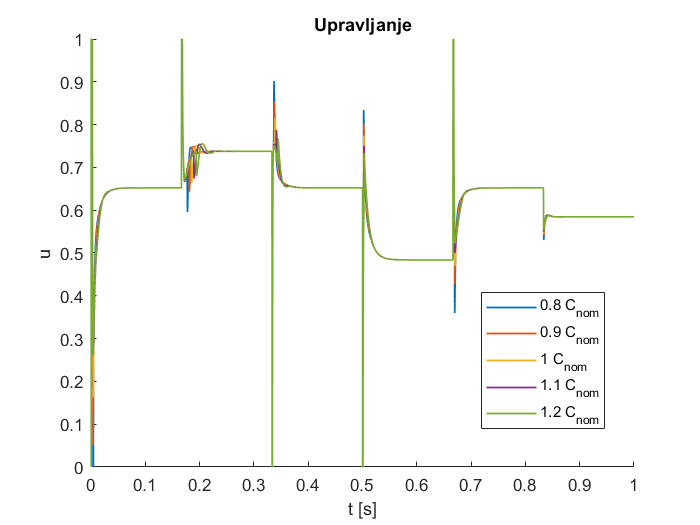

y_oznaka = "u";
naslov = "Upravljanje";
target_timeseries = out.upravljanje;
ref_flg = false;
poremecaj_flg = false;

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_celog_signala(fig, naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
    labels{i} = relative_vals(i) + " C_{nom}";
end
legend(plts, labels, 'Location', 'best')

Prelazak ka nominalnom rezimu rada

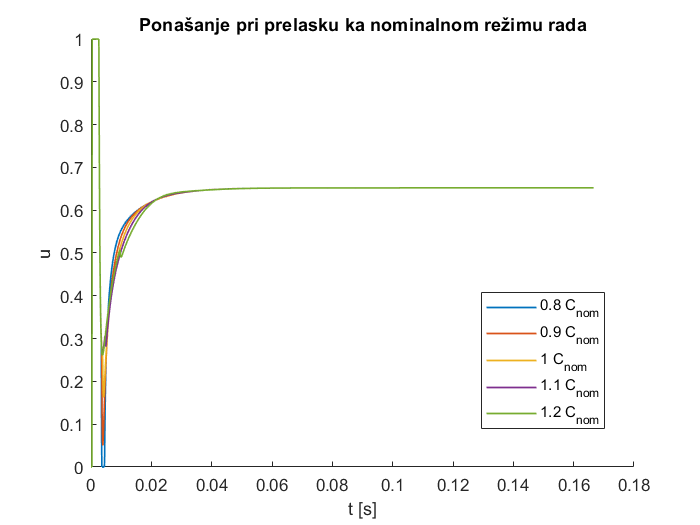

naslov = "Ponašanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = t_ref(1);

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = relative_vals(i) + " C_{nom}";
end
legend(plts, labels, 'Location', 'best')

Odziv na referencu

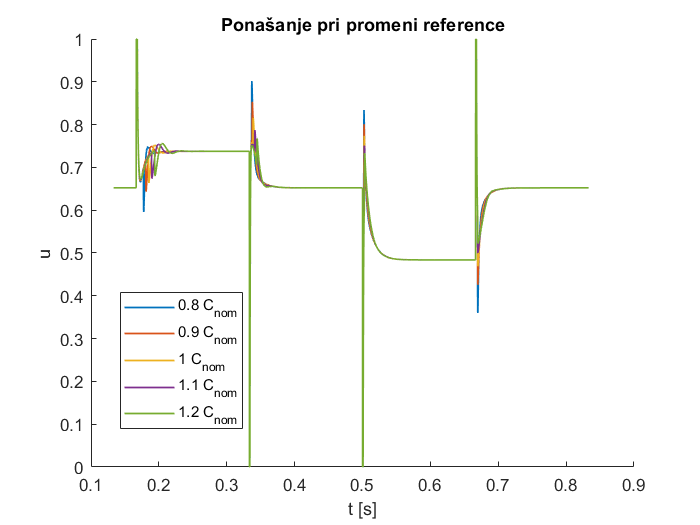

naslov = "Ponašanje pri promeni reference";
t_start = 0.8*t_ref(1);
t_end = t_poremecaj(1);

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = relative_vals(i) + " C_{nom}";
end
legend(plts, labels, 'Location', 'best')

Poremecaj

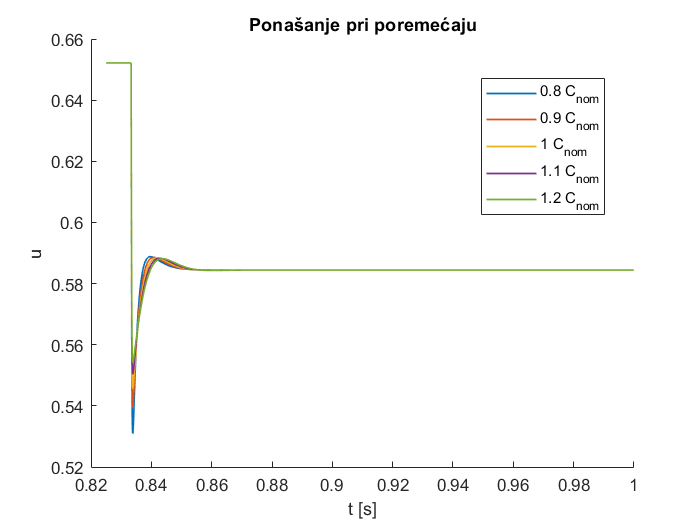

naslov = "Ponašanje pri poremećaju";
t_start = 0.99 * t_poremecaj(1);
t_end = sim_duration;

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    target_timeseries = out(i).upravljanje;
    plts(i) = crtanje_segmenta_vremena(fig , naslov, y_oznaka, out(i), target_timeseries, t_start, t_end, main_plot_linewidth);
    labels{i} = relative_vals(i) + " C_{nom}";
end
legend(plts, labels, 'Location', 'best')

#### Fazni portret

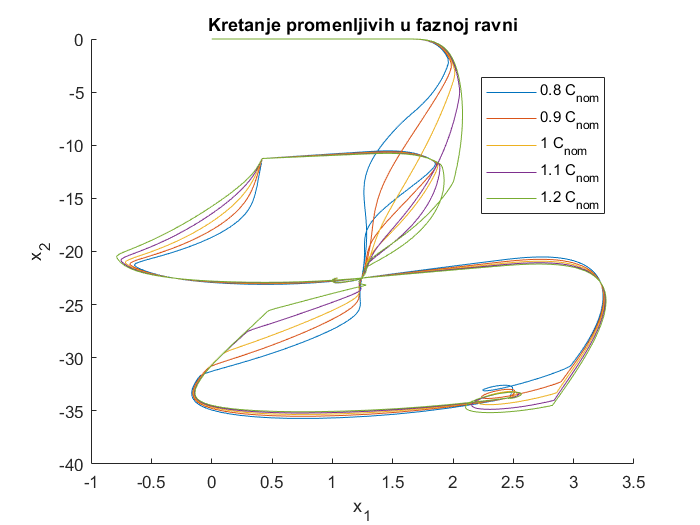

plts = [];
labels = {};

fig = figure();
hold on;
for i = 1:length(C_array)
    plts(i) = plot(out(i).x1.Data, out(i).x2.Data);
    labels{i} = relative_vals(i) + " C_{nom}";
end
title("Kretanje promenljivih u faznoj ravni")
xlabel("x_1")
ylabel("x_2")
legend(plts, labels, 'Location', 'best')